
    [lat1,lon1,UTCDateTime1]=PlotGPSlog("RTK_GPS\GPS_Right_Forest_True.ubx");
    [lat2,lon2,UTCDateTime2]=PlotGPSlog("RTK_GPS\GPS_Left_Forest_True.ubx");
    
    % Check Starts of Data
    if  UTCDateTime1(1,1)==UTCDateTime2(1,1)
        for i=1:size(lat1,2)
            if  UTCDateTime1(1,i)==UTCDateTime2(1,1)
                start=i;
                disp("Found Start 2")
            break
            end
        end
        sizearray=size(lat2,2);
        lat1new=lat1(1,start:start+sizearray-1);
        lon1new=lon1(1,start:start+sizearray-1);
        lat2new=lat2(1,1:size(lat1new,2));
        lon2new=lon2(1,1:size(lat1new,2));
    
    else
        for i=1:size(lat2,2)
            if  UTCDateTime1(1,1)==UTCDateTime2(1,i)
            start=i;
            disp("Found Start 1")
            break
            end
        end
    
        % Check ends of Data
        if UTCDateTime1(1,end)< UTCDateTime2(1,end)
            sizearray=size(lat1,2);
            lat2new=lat2(1,start:start+sizearray-1);
            lon2new=lon2(1,start:start+sizearray-1);
            lat1new=lat1(1,1:size(lat2new,2));
            lon1new=lon1(1,1:size(lat2new,2));
        else
             lat2new=lat2(1,start:end);
             lon2new=lon2(1,start:end);
             length=size(lon2new,2);
            lat1new=lat1(1,1:length);
            lon1new=lon1(1,1:length);
        end
    end

Found Start 1


    Ymid=zeros(size(lon1new,2),1);
    Xmid=zeros(size(lon1new,2),1);
     X1=zeros(size(lon1new,2),1);
    Y2=zeros(size(lon1new,2),1);
     X2=zeros(size(lon1new,2),1);
    Y1=zeros(size(lon1new,2),1);
    middlelat=zeros(size(lon1new,2),1);
    middlelon=zeros(size(lon1new,2),1);
    latMid=zeros(size(lon1new,2),1);
    lonMid=zeros(size(lon1new,2),1);
    bear1=zeros(size(lon1new,2),1);

    for i=1:size(lat2new,2)
        lat1 = lat1new(1,i) * pi/180; % latitude of current pos
        lon1 = lon1new(1,i) * pi/180; % longitude of current pos
        lat2 = lat2new(1,i)* pi/180; % latitude of destination
        lon2 = lon2new(1,i) * pi/180; % longitude of destination
        [latMid(i),lonMid(i)]= Midpoint2GPS(lat1,lon1,lat2,lon2);
        [~,~,bear]= DistBetween2GPS(lat1,lon1,lat2,lon2);
        bear = bear-90;
        
            if bear<-180
                bear=360+bear;
            end
 bear1(i)=bear;
        if i==1
            middlelatref=latMid(1)
             middlelonref=lonMid(1)

        end

        [Y,X,~]=DistBetween2GPS(deg2rad(middlelatref),deg2rad(middlelonref),deg2rad(latMid(i)),deg2rad(lonMid(i)));
         dist=-1;
         Ymid(i)=Y+dist*sind(bear);
         Xmid(i)=X+dist*cosd(bear);
        [Y1(i),X1(i),~]=DistBetween2GPS(deg2rad(middlelatref),deg2rad(middlelonref),lat1,lon1);
        [Y2(i),X2(i),~]=DistBetween2GPS(deg2rad(middlelatref),deg2rad(middlelonref),lat2,lon2);

%         

    end

middlelatref = 42.2914

middlelonref = -71.2589

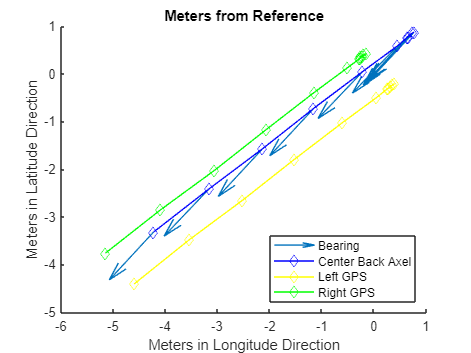

    % waypoints=[middlelat(15:2:end);middlelon(15:2:end)];
    waypoints=[Ymid,Xmid];


    start=1;
section=20;
    clf
    figure(1)
     hold on
     title("Meters from Reference")
     xlabel('Meters in Longitude Direction') 
    ylabel('Meters in Latitude Direction') 
    quiver(Xmid(start:section),Ymid(start:section),cosd(bear1(start:section)),sind(bear1(start:section)))
plot(Xmid(start:section),Ymid(start:section),'-bd');
plot(X1(start:section),Y1(start:section),'-yd');
plot(X2(start:section),Y2(start:section),'-gd');

     legend({'Bearing','Center Back Axel','Left GPS','Right GPS'},'Location','southeast')
hold off

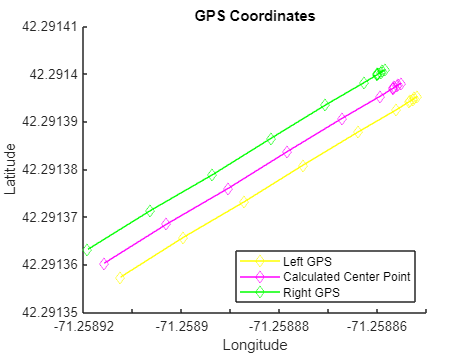



clf
figure(2)
hold on
title("GPS Coordinates")
     xlabel('Longitude') 
    ylabel('Latitude') 
 plot(lon1new(1,start:section),lat1new(1,start:section),'-yd');
  plot(lonMid(start:section),latMid(start:section),'-md');
 plot(lon2new(1,start:section),lat2new(1,start:section),'-gd');
 legend({'Left GPS','Calculated Center Point','Right GPS'},'Location','southeast')
hold off